%% initialize environments
clc;
clear variables;

ltas = 0;
for file_index = 1 : 1
    %% set AudioFileManipulator class parameters noMask
    input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word " + int2str(file_index) + ".wav";
    audio_file_manipulator = AudioFileManipulator(input_file_path);
    audio_file_manipulator.load_properties();

    %% set label file path and load label
    label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word " + int2str(file_index) + "_label.txt";
    label = sploadlabel(label_file_path, 'sec', audio_file_manipulator.sample_rate);

    for phoneme_index = 1 : (length(label) - 1)
        start_point = int32(label(phoneme_index).time * audio_file_manipulator.sample_rate);
        end_point = int32(label(phoneme_index + 1).time * audio_file_manipulator.sample_rate);
        [basic_frequencies, aperiodicity_parameters] = exstraightsource(audio_file_manipulator.signal(start_point : end_point), audio_file_manipulator.sample_rate);
        power_spectrogram = exstraightspec(audio_file_manipulator.signal(start_point : end_point), basic_frequencies, audio_file_manipulator.sample_rate);
        column_size = size(power_spectrogram, 2);      
        ltas = sum(power_spectrogram, 2) ./ column_size;
    end
end
%% make long term average spectrum dictionary related to phoneme
phoneme_list_counter = dictionary("a", 0);

for file_index = 1 : 50
    %% set AudioFileManipulator class parameters noMask
    input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word " + int2str(file_index) + ".wav";
    audio_file_manipulator = AudioFileManipulator(input_file_path);
    audio_file_manipulator.load_properties();

    %% set label file path and load label
    label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word " + int2str(file_index) + "_label.txt";
    label = sploadlabel(label_file_path, 'sec', audio_file_manipulator.sample_rate);

    %% count phoneme numbers
    for phoneme_index = 1 : (length(label) - 1)
        if isKey(phoneme_list_counter, label(phoneme_index).phoneme)
            phoneme_list_counter(label(phoneme_index).phoneme) = phoneme_list_counter(label(phoneme_index).phoneme) +1;
        else
            phoneme_list_counter(label(phoneme_index).phoneme) = 1;
        end
    end
end
%% make long term average spectrum dictionary related to phoneme
phoneme_list_spectrum = zeros(length(keys(phoneme_list_counter)), length(ltas));
for file_index = 1 : 50
    %% set AudioFileManipulator class parameters noMask
    input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word " + int2str(file_index) + ".wav";
    audio_file_manipulator = AudioFileManipulator(input_file_path);
    audio_file_manipulator.load_properties();

    %% set label file path and load label
    label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word " + int2str(file_index) + "_label.txt";
    label = sploadlabel(label_file_path, 'sec', audio_file_manipulator.sample_rate);

    for phoneme_index = 1 : (length(label) - 1)
        start_point = int32(label(phoneme_index).time * audio_file_manipulator.sample_rate);
        end_point = int32(label(phoneme_index + 1).time * audio_file_manipulator.sample_rate);
        [basic_frequencies, aperiodicity_parameters] = exstraightsource(audio_file_manipulator.signal(start_point : end_point), audio_file_manipulator.sample_rate);
        power_spectrogram = exstraightspec(audio_file_manipulator.signal(start_point : end_point), basic_frequencies, audio_file_manipulator.sample_rate);
        column_size = size(power_spectrogram, 2);      
        ltas = sum(power_spectrogram, 2) ./ column_size;
        phoneme_list_spectrum(calculate_dictionary_index(phoneme_list_counter, label(phoneme_index).phoneme), :) = phoneme_list_spectrum(calculate_dictionary_index(phoneme_list_counter, label(phoneme_index).phoneme), :) + ltas';
    end
end

%% make long term average spectrum dictionary related to phoneme
phoneme_list_counter_withMask = dictionary("a", 0);

for file_index = 1 : 50
    %% set AudioFileManipulator class parameters noMask
    input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word " + int2str(file_index) + ".wav";
    audio_file_manipulator = AudioFileManipulator(input_file_path);
    audio_file_manipulator.load_properties();

    %% set label file path and load label
    label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word " + int2str(file_index) + "_label.txt";
    label = sploadlabel(label_file_path, 'sec', audio_file_manipulator.sample_rate);

    %% count phoneme numbers
    for phoneme_index = 1 : (length(label) - 1)
        if isKey(phoneme_list_counter_withMask, label(phoneme_index).phoneme)
            phoneme_list_counter_withMask(label(phoneme_index).phoneme) = phoneme_list_counter_withMask(label(phoneme_index).phoneme) +1;
        else
            phoneme_list_counter_withMask(label(phoneme_index).phoneme) = 1;
        end
    end
end

%% make long term average spectrum dictionary related to phoneme
phoneme_list_spectrum_withMask = zeros(length(keys(phoneme_list_counter_withMask)), length(ltas));
for file_index = 1 : 50
    %% set AudioFileManipulator class parameters noMask
    input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word " + int2str(file_index) + ".wav";
    audio_file_manipulator = AudioFileManipulator(input_file_path);
    audio_file_manipulator.load_properties();

    %% set label file path and load label
    label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word " + int2str(file_index) + "_label.txt";
    label = sploadlabel(label_file_path, 'sec', audio_file_manipulator.sample_rate);

    for phoneme_index = 1 : (length(label) - 1)
        start_point = int32(label(phoneme_index).time * audio_file_manipulator.sample_rate);
        end_point = int32(label(phoneme_index + 1).time * audio_file_manipulator.sample_rate);
        [basic_frequencies, aperiodicity_parameters] = exstraightsource(audio_file_manipulator.signal(start_point : end_point), audio_file_manipulator.sample_rate);
        power_spectrogram = exstraightspec(audio_file_manipulator.signal(start_point : end_point), basic_frequencies, audio_file_manipulator.sample_rate);
        column_size = size(power_spectrogram, 2);      
        ltas = sum(power_spectrogram, 2) ./ column_size;
        phoneme_list_spectrum_withMask(calculate_dictionary_index(phoneme_list_counter_withMask, label(phoneme_index).phoneme), :) = phoneme_list_spectrum_withMask(calculate_dictionary_index(phoneme_list_counter_withMask, label(phoneme_index).phoneme), :) + ltas';
    end
end

for phoneme_index = 1 : length(keys(phoneme_list_counter))
    grid on;
    hold on;
    legend;
    key_list = keys(phoneme_list_counter);
    key_list_withMask = keys(phoneme_list_counter_withMask);
    output_png_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト Compare phoneme/set1_comparison " + int2str(phoneme_index) + ".png";
    fftl = (length(phoneme_list_spectrum(phoneme_index, :))-1)*2;                         %fftlを新たに定義
    x = ((0:fftl/2)*audio_file_manipulator.sample_rate/fftl)';                         %横軸をHzで表
    if key_list(phoneme_index) ~= key_list_withMask(phoneme_index)
        disp(key_list, key_list_withMask);
    end
    ltas_decibel = 10 * log10(phoneme_list_spectrum(phoneme_index, :) / phoneme_list_counter(key_list(phoneme_index)));
    plot(x, ltas_decibel, "DisplayName", "noMask");
    ltas_decibel = 10 * log10(phoneme_list_spectrum_withMask(phoneme_index, :) / phoneme_list_counter_withMask(key_list_withMask(phoneme_index)));                   %dB値に変換
    plot(x, ltas_decibel, "DisplayName", "withMask");
    title("Set1 comparison ltas phoneme " + key_list(phoneme_index));
    xlim([0 floor(audio_file_manipulator.sample_rate / 4)]);
    ylim([-40 0]);
    xlabel("frequency [Hz]");
    ylabel("long term average spectrum Magnitude [dB]");
    saveas(gcf, output_png_path);
    delete(gcf);
end

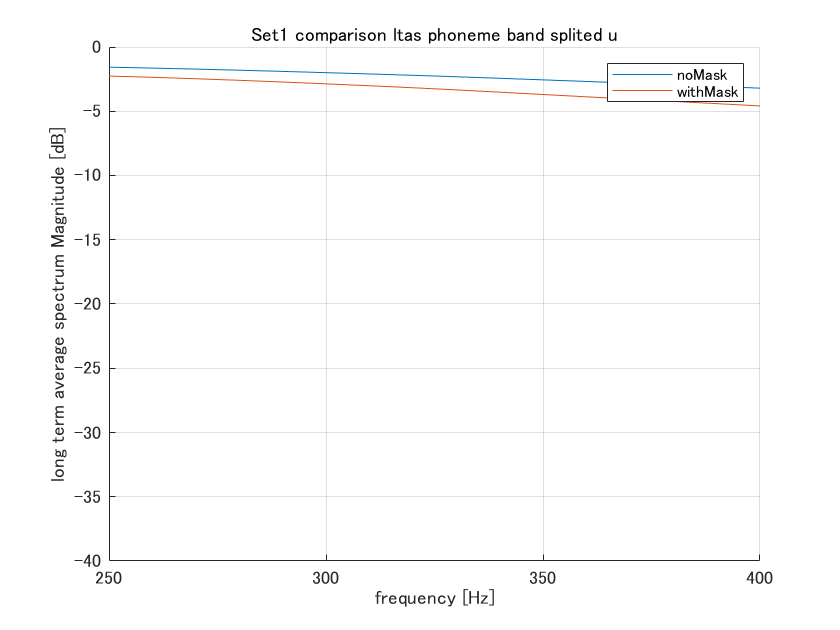

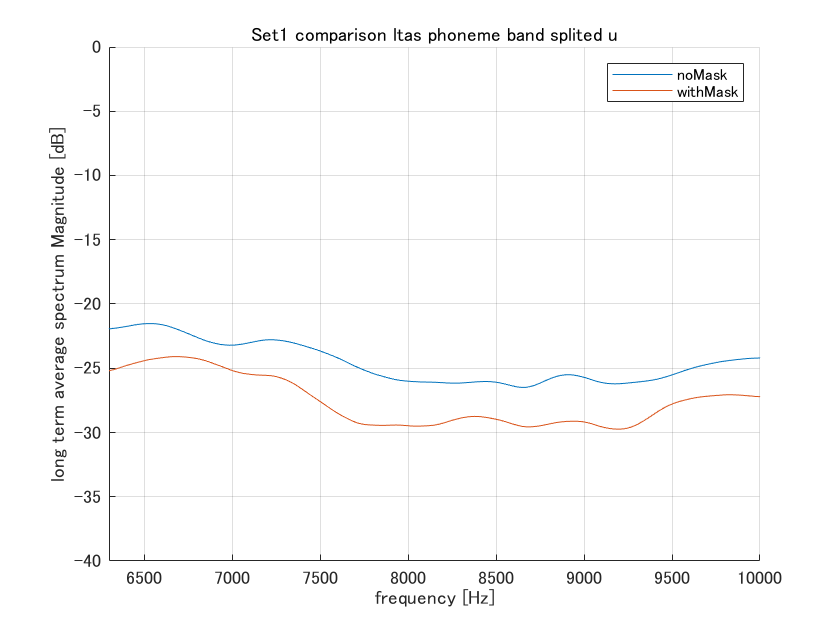

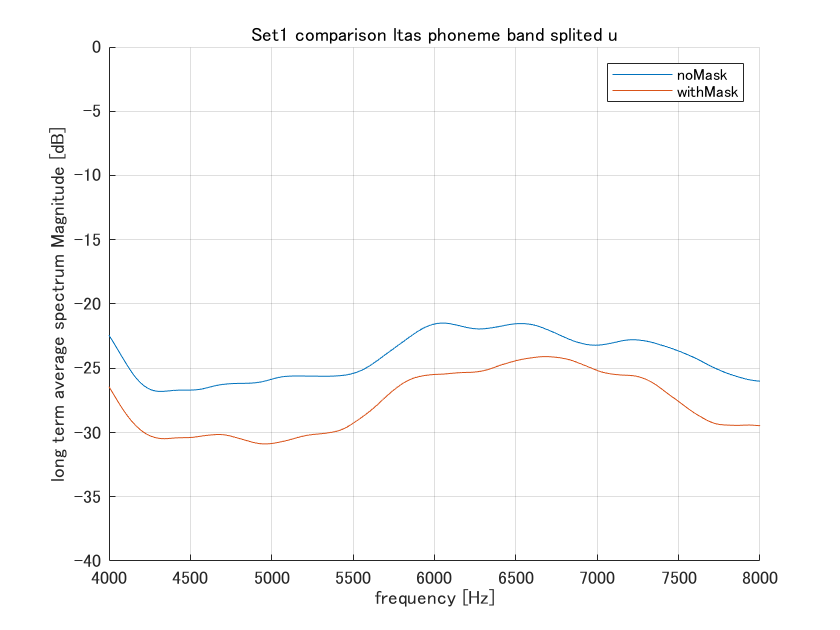

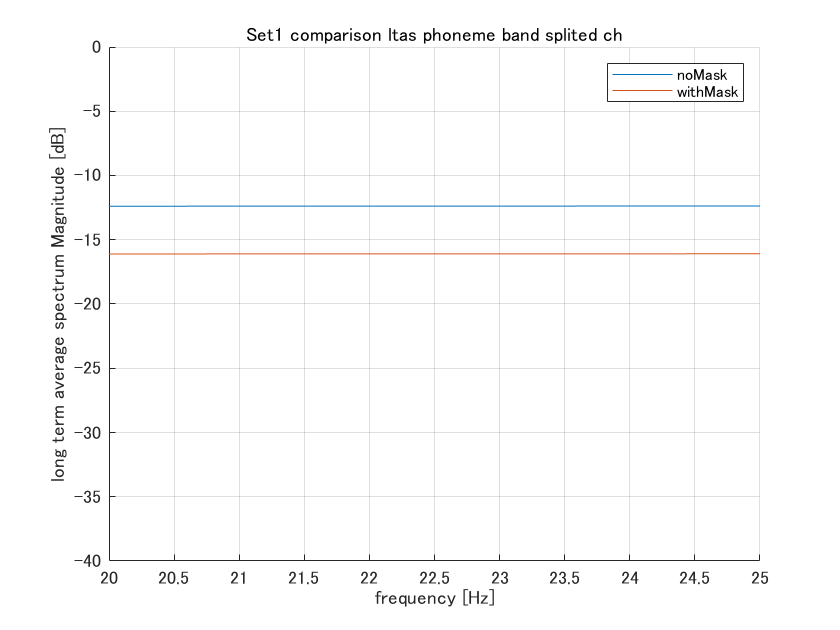

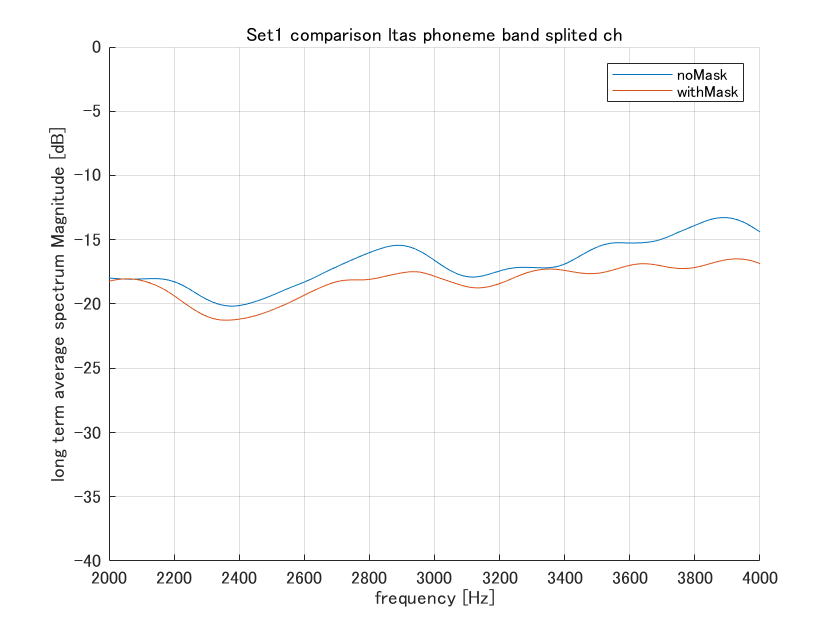

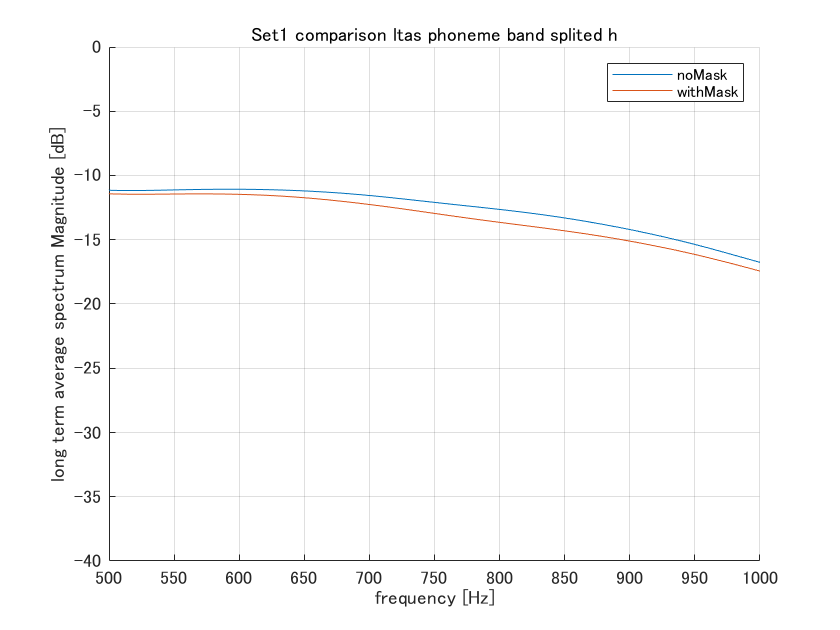

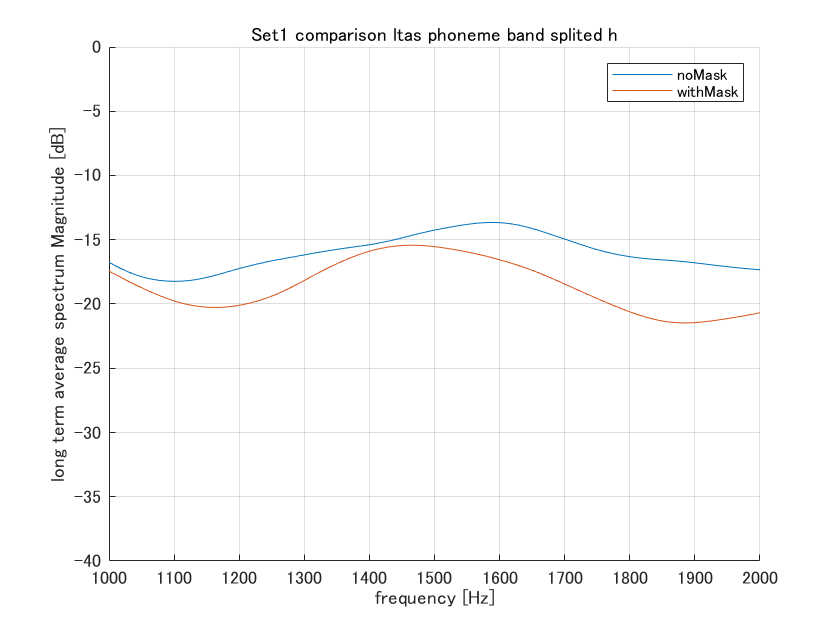

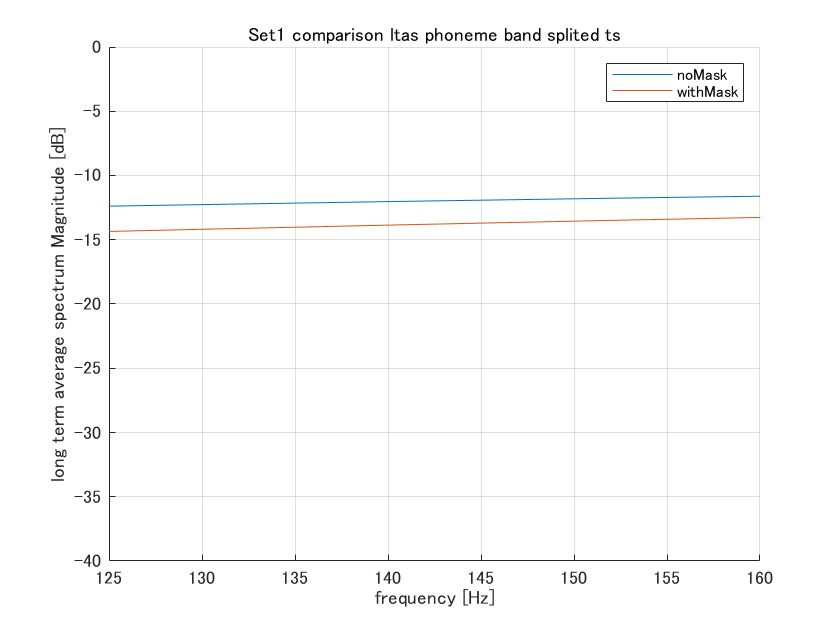

for phoneme_index = 1 : length(keys(phoneme_list_counter))
    % 31バンドの場合
    band_split_list = [20, 25, 31.5, 40, 50, 63, 80, 100, 125, 160, 200, 250, 315, 400, 500, 630, 800, 1000, 1250, 1600, 2000, 2500, 3150, 4000, 5000, 6300, 8000, 10000, 12500, 16000, 20000];
    for band_index = 1 : (length(band_split_list) - 1)
        grid on;
        hold on;
        legend;
        key_list = keys(phoneme_list_counter);
        key_list_withMask = keys(phoneme_list_counter_withMask);
        output_png_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト Compare phoneme band split/set1_comparison " + int2str(phoneme_index) + "_" + int2str(band_split_list(band_index)) + "_" + int2str(band_split_list(band_index + 1)) + ".png";
        fftl = (length(phoneme_list_spectrum(phoneme_index, :))-1)*2;                         %fftlを新たに定義
        x = ((0:fftl/2)*audio_file_manipulator.sample_rate/fftl)';                         %横軸をHzで表
        if key_list(phoneme_index) ~= key_list_withMask(phoneme_index)
            disp(key_list, key_list_withMask);
        end
        ltas_decibel = 10 * log10(phoneme_list_spectrum(phoneme_index, :) / phoneme_list_counter(key_list(phoneme_index)));
        plot(x, ltas_decibel, "DisplayName", "noMask");
        ltas_decibel = 10 * log10(phoneme_list_spectrum_withMask(phoneme_index, :) / phoneme_list_counter_withMask(key_list_withMask(phoneme_index)));                   %dB値に変換
        plot(x, ltas_decibel, "DisplayName", "withMask");
        title("Set1 comparison ltas phoneme band splited " + key_list(phoneme_index));
        xlim([band_split_list(band_index), band_split_list(band_index + 1)]);
        ylim([-40 0]);
        xlabel("frequency [Hz]");
        ylabel("long term average spectrum Magnitude [dB]");
        saveas(gcf, output_png_path);
        delete(gcf);
    end

    % 15バンドの場合
    band_split_list = [25, 40, 63, 100, 160, 250, 400, 630, 1000, 1600, 2500, 4000, 6300, 10000, 16000];
    for band_index = 1 : (length(band_split_list) - 1)
        grid on;
        hold on;
        legend;
        key_list = keys(phoneme_list_counter);
        key_list_withMask = keys(phoneme_list_counter_withMask);
        output_png_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト Compare phoneme band split/set1_comparison " + int2str(phoneme_index) + "_" + int2str(band_split_list(band_index)) + "_" + int2str(band_split_list(band_index + 1)) + ".png";
        fftl = (length(phoneme_list_spectrum(phoneme_index, :))-1)*2;                         %fftlを新たに定義
        x = ((0:fftl/2)*audio_file_manipulator.sample_rate/fftl)';                         %横軸をHzで表
        if key_list(phoneme_index) ~= key_list_withMask(phoneme_index)
            disp(key_list, key_list_withMask);
        end
        ltas_decibel = 10 * log10(phoneme_list_spectrum(phoneme_index, :) / phoneme_list_counter(key_list(phoneme_index)));
        plot(x, ltas_decibel, "DisplayName", "noMask");
        ltas_decibel = 10 * log10(phoneme_list_spectrum_withMask(phoneme_index, :) / phoneme_list_counter_withMask(key_list_withMask(phoneme_index)));                   %dB値に変換
        plot(x, ltas_decibel, "DisplayName", "withMask");
        title("Set1 comparison ltas phoneme band splited " + key_list(phoneme_index));
        xlim([band_split_list(band_index), band_split_list(band_index + 1)]);
        ylim([-40 0]);
        xlabel("frequency [Hz]");
        ylabel("long term average spectrum Magnitude [dB]");
        saveas(gcf, output_png_path);
        delete(gcf);
    end

    % 10バンドの場合
    band_split_list = [31.25, 62.5, 125, 250, 500, 1000, 2000, 4000, 8000, 16000];
    for band_index = 1 : (length(band_split_list) - 1)
        grid on;
        hold on;
        legend;
        key_list = keys(phoneme_list_counter);
        key_list_withMask = keys(phoneme_list_counter_withMask);
        output_png_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト Compare phoneme band split/set1_comparison " + int2str(phoneme_index) + "_" + int2str(band_split_list(band_index)) + "_" + int2str(band_split_list(band_index + 1)) + ".png";
        fftl = (length(phoneme_list_spectrum(phoneme_index, :))-1)*2;                         %fftlを新たに定義
        x = ((0:fftl/2)*audio_file_manipulator.sample_rate/fftl)';                         %横軸をHzで表
        if key_list(phoneme_index) ~= key_list_withMask(phoneme_index)
            disp(key_list, key_list_withMask);
        end
        ltas_decibel = 10 * log10(phoneme_list_spectrum(phoneme_index, :) / phoneme_list_counter(key_list(phoneme_index)));
        plot(x, ltas_decibel, "DisplayName", "noMask");
        ltas_decibel = 10 * log10(phoneme_list_spectrum_withMask(phoneme_index, :) / phoneme_list_counter_withMask(key_list_withMask(phoneme_index)));                   %dB値に変換
        plot(x, ltas_decibel, "DisplayName", "withMask");
        title("Set1 comparison ltas phoneme band splited " + key_list(phoneme_index));
        xlim([band_split_list(band_index), band_split_list(band_index + 1)]);
        ylim([-40 0]);
        xlabel("frequency [Hz]");
        ylabel("long term average spectrum Magnitude [dB]");
        saveas(gcf, output_png_path);
        delete(gcf);
    end

    % 5バンドの場合
    band_split_list = [20, 100, 500, 2500, 12500];
    for band_index = 1 : (length(band_split_list) - 1)
        grid on;
        hold on;
        legend;
        key_list = keys(phoneme_list_counter);
        key_list_withMask = keys(phoneme_list_counter_withMask);
        output_png_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト Compare phoneme band split/set1_comparison " + int2str(phoneme_index) + "_" + int2str(band_split_list(band_index)) + "_" + int2str(band_split_list(band_index + 1)) + ".png";
        fftl = (length(phoneme_list_spectrum(phoneme_index, :))-1)*2;                         %fftlを新たに定義
        x = ((0:fftl/2)*audio_file_manipulator.sample_rate/fftl)';                         %横軸をHzで表
        if key_list(phoneme_index) ~= key_list_withMask(phoneme_index)
            disp(key_list, key_list_withMask);
        end
        ltas_decibel = 10 * log10(phoneme_list_spectrum(phoneme_index, :) / phoneme_list_counter(key_list(phoneme_index)));
        plot(x, ltas_decibel, "DisplayName", "noMask");
        ltas_decibel = 10 * log10(phoneme_list_spectrum_withMask(phoneme_index, :) / phoneme_list_counter_withMask(key_list_withMask(phoneme_index)));                   %dB値に変換
        plot(x, ltas_decibel, "DisplayName", "withMask");
        title("Set1 comparison ltas phoneme band splited " + key_list(phoneme_index));
        xlim([band_split_list(band_index), band_split_list(band_index + 1)]);
        ylim([-40 0]);
        xlabel("frequency [Hz]");
        ylabel("long term average spectrum Magnitude [dB]");
        saveas(gcf, output_png_path);
        delete(gcf);
    end

    % 5バンドの場合
    band_split_list = [0, 630, 4000, 8000, 12500];
    for band_index = 1 : (length(band_split_list) - 1)
        grid on;
        hold on;
        legend;
        key_list = keys(phoneme_list_counter);
        key_list_withMask = keys(phoneme_list_counter_withMask);
        output_png_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト Compare phoneme band split/set1_comparison " + int2str(phoneme_index) + "_" + int2str(band_split_list(band_index)) + "_" + int2str(band_split_list(band_index + 1)) + ".png";
        fftl = (length(phoneme_list_spectrum(phoneme_index, :))-1)*2;                         %fftlを新たに定義
        x = ((0:fftl/2)*audio_file_manipulator.sample_rate/fftl)';                         %横軸をHzで表
        if key_list(phoneme_index) ~= key_list_withMask(phoneme_index)
            disp(key_list, key_list_withMask);
        end
        ltas_decibel = 10 * log10(phoneme_list_spectrum(phoneme_index, :) / phoneme_list_counter(key_list(phoneme_index)));
        plot(x, ltas_decibel, "DisplayName", "noMask");
        ltas_decibel = 10 * log10(phoneme_list_spectrum_withMask(phoneme_index, :) / phoneme_list_counter_withMask(key_list_withMask(phoneme_index)));                   %dB値に変換
        plot(x, ltas_decibel, "DisplayName", "withMask");
        title("Set1 comparison ltas phoneme band splited " + key_list(phoneme_index));
        xlim([band_split_list(band_index), band_split_list(band_index + 1)]);
        ylim([-40 0]);
        xlabel("frequency [Hz]");
        ylabel("long term average spectrum Magnitude [dB]");
        saveas(gcf, output_png_path);
        delete(gcf);
    end
end

function [index] = calculate_dictionary_index(dictionary, key)
    index = 1;
    key_list = keys(dictionary);
    for key_index = 1 : length(key_list)
        if key_list(key_index) == key
            index = key_index;
            break;
        end
    end
end